T = [.7 .2 .3
     .2 .3 .3
     .1 .5 .4];

% Posições na matriz
SOL = 1

SOL = 1

NUVENS = 2

NUVENS = 2

CHUVA = 3

CHUVA = 3

## c


v = [1;0;0];
v2 = T^2*v;
resp = v2(CHUVA);

fprintf("%d\n",resp);

2.100000e-01


## d


n = 20

n = 20


M = T(:);

for i = 2:n

    aux = T^i;
    M = [M aux(:)];

end

M

M =     0.7000    0.5600    0.5010    0.4760    0.4654    0.4609    0.4590    0.4582    0.4579    0.4577    0.4577    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576
    0.2000    0.2300    0.2440    0.2499    0.2524    0.2535    0.2539    0.2541    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542
    0.1000    0.2100    0.2550    0.2741    0.2822    0.2856    0.2871    0.2877    0.2879    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881    0.2881
    0.2000    0.3500    0.4120    0.4383    0.4494    0.4542    0.4562    0.4570    0.4574    0.4575    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576    0.4576
    0.3000    0.2800    0.2650    0.2588    0.2562    0.2551    0.2546    0.2544    0.2543    0.2543    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542    0.2542  

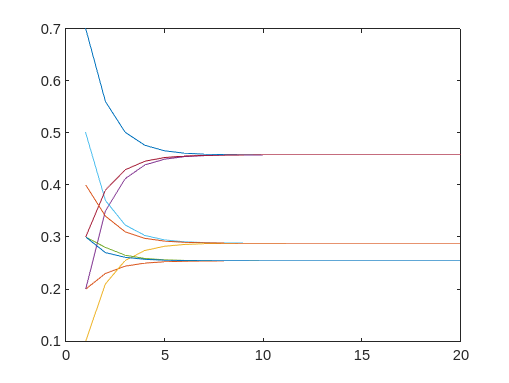

plot(M')

## e


previous = T;

while 1
    %iter n
    %iter n+1
    n1 = T* previous;
   
    %diferença
    dif = max(max(abs(n1-previous)));
    
    % se dif < limiar
    % END

    if dif < 1e-16
        break
    end

    % atualizar o previous
    previous = n1;
end


## f

M = [T - eye(3); ones(1,3)];

b = [zeros(3,1); 1];

u = M\b;



## 2

## a


H = [.8 .2 0 0
     0 .9 .1 0
     .3 .2 .4 .1
     0 0 0 1];


## b

v = [1 0 0 0]';

res = H^1000*v;

res(2)

ans = 1.3212e-06

ou

H1000 = H^1000

H1000 =     0.0000    0.0000    0.0000    1.0000
    0.0000    0.0000    0.0000    1.0000
    0.0000    0.0000    0.0000    1.0000
         0         0         0    1.0000


res = H1000(2,1)

res = 1.3212e-06

## c

T^10

ans =     0.4577    0.4575    0.4576
    0.2542    0.2543    0.2543
    0.2881    0.2882    0.2882


T^1000

ans =     0.4576    0.4576    0.4576
    0.2542    0.2542    0.2542
    0.2881    0.2881    0.2881


## d


num_estados_nao_absorventes = 3;
Q = H(1:num_estados_nao_absorventes,1:num_estados_nao_absorventes)

Q =     0.8000    0.2000         0
         0    0.9000    0.1000
    0.3000    0.2000    0.4000


## e

F = inv(eye(num_estados_nao_absorventes) - Q)'

F =    20.0000   15.0000   15.0000
   60.0000   60.0000   50.0000
   10.0000   10.0000   10.0000




% nº de vezes que se passa em cada ppagina, começando em 1, 2, oou 3

## f

sum(F)

ans =    90.0000   85.0000   75.0000



% primeiro valor para a primeira págna, 2º valor para a 2ª página, 3 valor
% para a 3 pagina

## g

## 3

## a)


N = 6;
A = 1, B = 2, C = 3, D = 4, E = 5, F = 6

A = 1

B = 2

C = 3

D = 4

E = 5

H = zeros(N);

H(B,A) = 1;
H(C,B) = 1;
H(E,B) = 1;
H(D,C) = 1;
H(C,D) = 1;
H(A,E) = 1;
H(B,E) = 1;
H(F,E) = 1;

saidas = sum(H);
H = H ./ saidas;
H(isnan(H)) = 0;
H

H =          0         0         0         0    0.3333         0
    1.0000         0         0         0    0.3333         0
         0    0.5000         0    1.0000         0         0
         0         0    1.0000         0         0         0
         0    0.5000         0         0         0         0
         0         0         0         0    0.3333         0


## b

% o dead end é o F
% a spider trap é entre C e D
